# Permutation DFA of K vs S for 7 acoustic groups

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'CallType', 'BatID','MPS_mic', 'MPS_mic_wf', 'MPS_mic_wt')
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'MicAudioGood','TmicAll7');
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);

Get color vectors ready

% Get the color vector ready for call type
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UCT = unique(CallType(~cellfun(@isempty, CallType)));
UCT = UCT([1:4 9 5:8 10:14])

UCT = 14×1 cell array
    {'BB' }
    {'Ba' }
    {'Bu' }
    {'Ch' }
    {'Pi' }
    {'LPi'}
    {'LT' }
    {'PB' }
    {'Pa' }
    {'Ra' }
    {'SB' }
    {'Sq' }
    {'Tr' }
    {'Un' }


UCTFull = UCT;
UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'LPi')} = 'Loud Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
UCTFull{strcmp(UCT, 'PB')} = 'Pitchy Call Buzz';
UCTFull{strcmp(UCT, 'SB')} = 'Squeal Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
IndNoCall = cellfun(@isempty, CallType);
CallType(IndNoCall) = {'Un'};
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

% Get the color vector ready for BatName, Sex and Deafness
GGPath = dir('/Users/elie/Google Drive*');
Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end

end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

First restrict the MPS spectral frequency to 3 cycles/kHz and normalized all MPS

addpath(genpath('/Users/elie/Documents/CODE/GitHub/umapDistribution'))
IndWf = (MPS_mic_wf*1000)<=3; % Max Spectral frequency taken into account in cycles/kHz
NVoc = sum(MicAudioGood01);
MPS_mic_norm = cell(1,NVoc);
MPS_mic_focus = cell(1,NVoc);
MPS_mic_mean = reshape(mean(MPS_mic(MicAudioGood01,:), 'omitnan')',length(MPS_mic_wf), length(MPS_mic_wt));
IndMicAudioGood = find(MicAudioGood01);
for nn=1:NVoc
    vv=IndMicAudioGood(nn);
    MPS_local = reshape(MPS_mic(vv,:)',length(MPS_mic_wf), length(MPS_mic_wt));
    MPS_local = MPS_local(IndWf,:);
    MPS_mic_norm{nn} = reshape(MPS_local./MPS_mic_mean(IndWf,:), numel(MPS_local),1);
    MPS_mic_focus{nn} = reshape(MPS_local, numel(MPS_local),1);
end
MPS_mic_norm = [MPS_mic_norm{:}]';
MPS_mic_focus = [MPS_mic_focus{:}]';
CCT_mic = CCT(MicAudioGood01,:);

For AllCalls run a PCA  and then a permutation DFA first for both male and females and then per sex


    fprintf(1,'-------------------------------------------------------------------------------\n')

-------------------------------------------------------------------------------


    fprintf(1,'-------------------------------------------------------------------------------\n')

-------------------------------------------------------------------------------


    fprintf(1,'-------------------------------All Calls----------------------------\n')

-------------------------------All Calls----------------------------


    [PC,Score,~, ~, VarExpl,~] = pca(MPS_mic_norm);

Plot the % variance explained by the PC

    figure()
    CSVarExpl = cumsum(VarExpl);
    plot(CSVarExpl, 'Linewidth',2)
    xlabel('# PC')
    ylabel('%variance explained for All Calls')
    NPC = find(cumsum(VarExpl)>90,1);
    text(100,95, sprintf('90%% variance explained with %d PC',NPC ))
    text(100,90, sprintf('%.1f%% variance explained with 100 PC', CSVarExpl(100)))

    save(fullfile(LocalDataDir, 'Data4_DeafBats_PermDFA_AllCalls.mat'), 'PC', 'Score', 'VarExpl', 'NPC')

    NRandPerm=10;

Permutation DFA for males only

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        Delta |        Gamma |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.66914 |       113.9 |     0.66914 |     0.66914 |       98.156 |      0.85796 |
|    2 | Accept |     0.66914 |      111.89 |     0.66914 |     0.66914 |       447.15 |     0.050549 |
|    3 | Best   |     0.29832 |      116.02 |     0.29832 |     0.29836 |   1.3357e-05 |      0.80971 |
|    4 | Accept |     0.30423 |      114.78 |     0.29832 |      0.2989 |   1.0229e-05 |     0.065991 |
|    5 | Accept |     0.29875 |      116.54 |     0.29832 |     0.29911 |   0.00033425 |      0.27038 |
|    6 | Accept |     0.30338 |      113.33 |     0.29832 |     

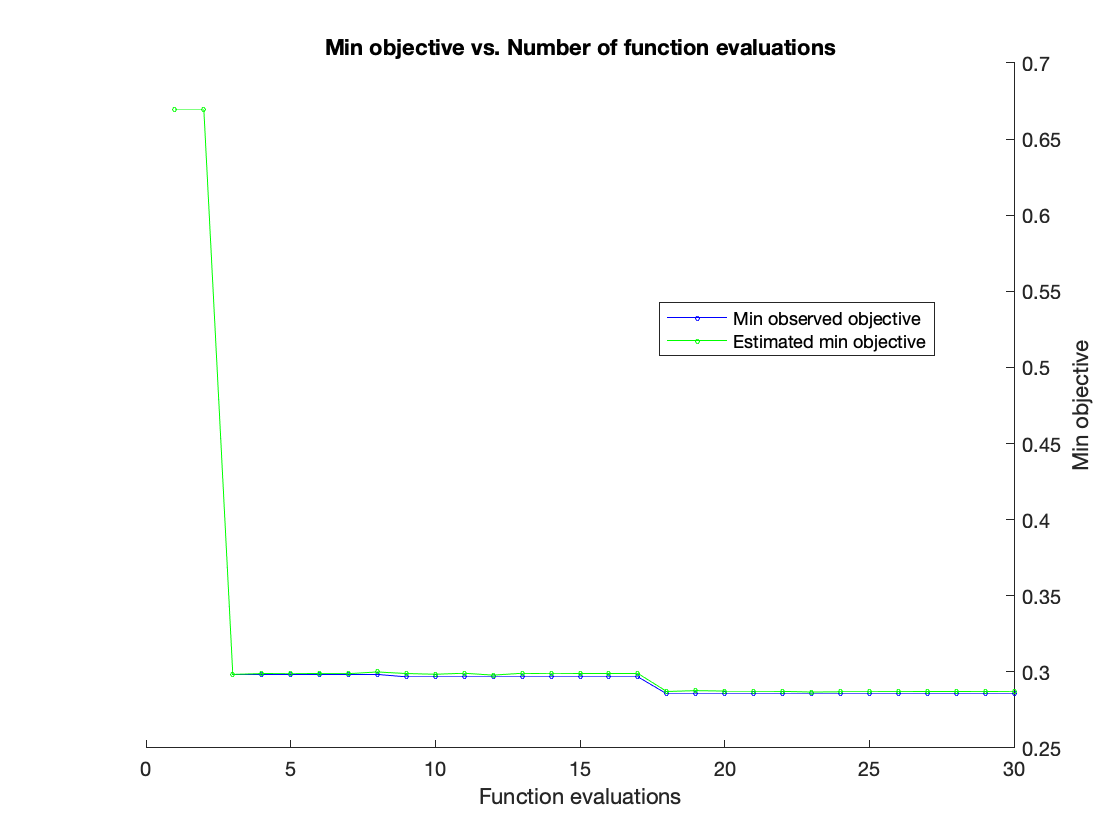

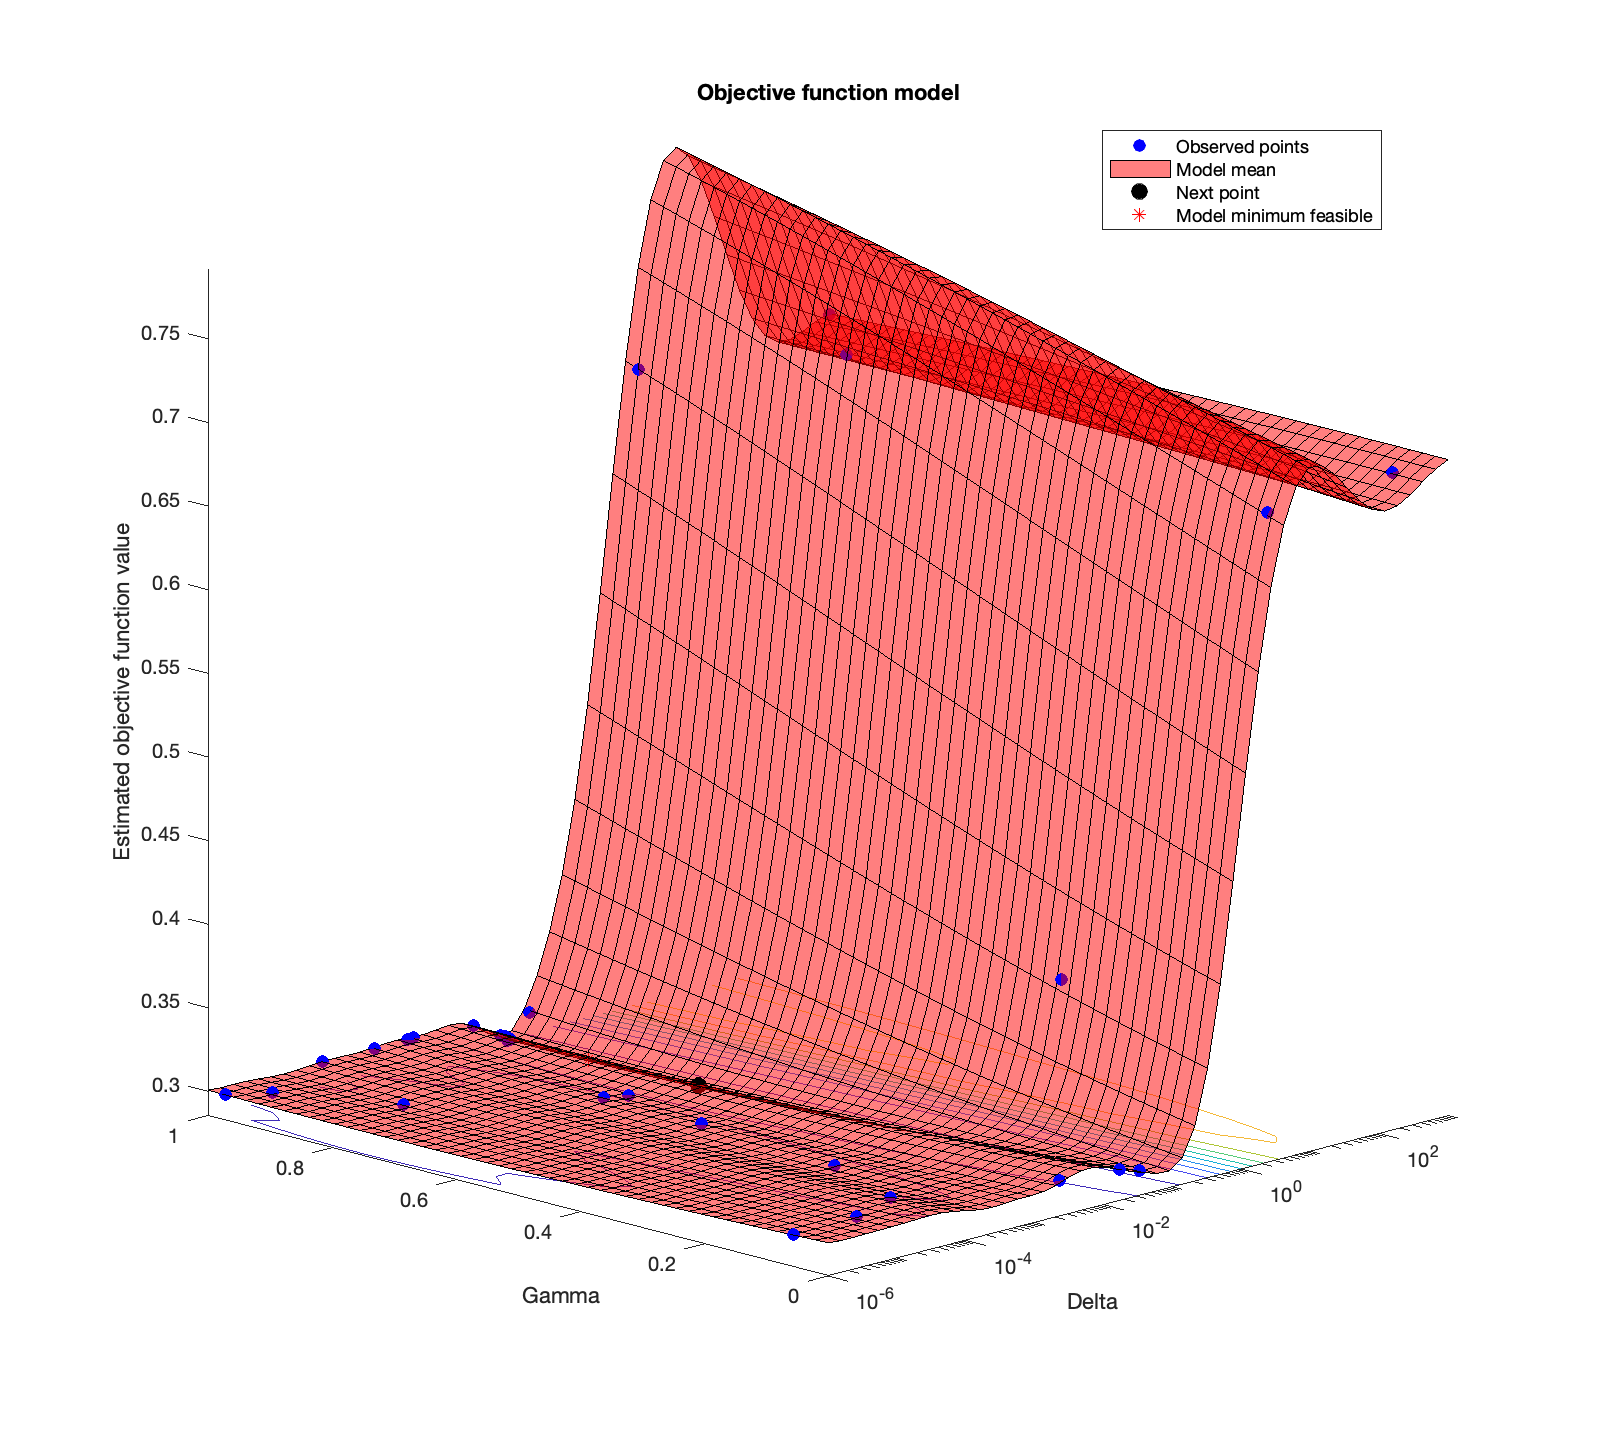


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 4141.3066 seconds
Total objective function evaluation time: 3366.4762

Best observed feasible point:
     Delta       Gamma 
    ________    _______

    0.019145    0.99272

Observed objective function value = 0.28557
Estimated objective function value = 0.28699
Function evaluation time = 122.2693

Best estimated feasible point (according to models):
     Delta       Gamma 
    ________    _______

    0.018916    0.98887

Estimated objective function value = 0.28695
Estimated function evaluation time = 112.0293



    SexDeafMic = SexDeaf(IndMicAudioGood);
    MaleLogical = contains(SexDeafMic, 'M');
    SexDeafMic_M=SexDeafMic(MaleLogical);
    
    % Find the optimal regularization parameters Delta and Gamma with a PC
    % input that explains 90% variance
    NPC = find(cumsum(VarExpl)>90,1);
    Mdl_DG_males = fitcdiscr(Score(MaleLogical, 1:NPC),SexDeafMic(MaleLogical), 'OptimizeHyperparameters', 'auto', 'HyperparameterOptimizationOptions', struct('Kfold',10), 'Prior', [0.5 0.5], 'SaveMemory', 'on', 'FillCoeffs', 'off');

    % Run the model with the best Delta and Gamma in cross validation and
    % get the Loss values accross validation sets
    Mdl = fitcdiscr(Score(MaleLogical, 1:NPC),SexDeafMic(MaleLogical), 'Delta', Mdl_DG_males.Delta, 'Gamma', Mdl_DG_males.Gamma, 'CrossVal','on', 'KFold', 10, 'Prior', [0.5 0.5], 'SaveMemory', 'on', 'FillCoeffs', 'off');
    L_males = kfoldLoss(Mdl, 'Mode', 'Individual');

    % Permutation of HD irrespective of ID
    Lrand_males = nan(NRandPerm,1);
    for bb=1:NRandPerm
        RandInd = randperm(length(SexDeafMic_M));
        Mdlrand = fitcdiscr(Score(MaleLogical,1:NPC),SexDeafMic_M(RandInd), 'Delta', Mdl_DG_males.Delta, 'Gamma', Mdl_DG_males.Gamma,'CrossVal','on', 'KFold', 10, 'Prior', [0.5 0.5], 'SaveMemory', 'on', 'FillCoeffs', 'off');
        Lrand_males(bb) = kfoldLoss(Mdlrand);
    end

    % permutation of HD respecting ID
    Lperm_males = nan(3,1);
    Perm_males = [1:6 7 9 8 10; 1:6 9 8 7 10; 1:6 7 9 10 8];
    BatIDMicGR = BatID(IndMicAudioGood);
    BatIDMicGR_M = BatIDMicGR(MaleLogical);
    for bb=1:3
        SexDeafMic_M_temp = SexDeafMic_M;
        BatSexDeaf_local = BatSexDeaf(Perm_males(bb,:));
        for bat=1:length(BatName)
            if sum(contains(BatIDMicGR_M,num2str(BatName(bat))))
                Ind = find(contains(BatIDMicGR_M,num2str(BatName(bat))));
                for ii=1:length(Ind)
                    SexDeafMic_M_temp{Ind(ii)} = BatSexDeaf_local{bat};
                end
            end
        end
        Mdlrand = fitcdiscr(Score(MaleLogical,1:NPC),SexDeafMic_M_temp, 'Delta', Mdl_DG_males.Delta, 'Gamma', Mdl_DG_males.Gamma, 'CrossVal','on', 'KFold', 10, 'Prior', [0.5 0.5], 'SaveMemory', 'on', 'FillCoeffs', 'off');
        Lperm_males(bb) = kfoldLoss(Mdlrand);
    end

    % Rerun the DFA with all the data to obtain the filter
    Mdl = fitcdiscr(Score(MaleLogical, 1:NPC),SexDeafMic(MaleLogical), 'Delta', Mdl_DG_males.Delta, 'Gamma', Mdl_DG_males.Gamma, 'Prior', [0.5 0.5], 'SaveMemory', 'off', 'FillCoeffs', 'on');
    % Mdl.BetweenSigma is the p-by-p matrix, the between-class covariance, where p is the number of predictors.
    % Mdl.Sigma % Within-class covariance matrix or matrices. The dimensions depend on DiscrimType: 'linear'...
    %  (default) — Matrix of size p-by-p, where p is the number of predictors
    % The firt PC of the pca of the between class covariance matrix divided
    % by within class covariance matrix is the first filter of the DFA in
    % DFA input space (first PCA above)
%     [EigenVect,~] = eig(Mdl.BetweenSigma,Mdl.Sigma);
%     PC_DF_males = PC(:,1:NPC) * EigenVect(:,1);
    [PC_DFA,~] = pca(Mdl.Sigma \ Mdl.BetweenSigma);
    PC_DF_males = PC(:,1:NPC) * PC_DFA(:,1);
    PC_DF_males = reshape(PC_DF_males, sum(IndWf), length(MPS_mic_wt));
    
    fprintf(1, 'Classification performance between K and S male calls: %.1f%% +/-%.1f%%\nPermutation value (respecting ID): %.1f%% +/-%.1f%%\nPermutation value (irrespective of ID): %.1f%% +/-%.1f%%\nGamma:%.2f and Delta:%.1e\n', mean((1-L_males)*100), std((1-L_males)*100),mean((1-Lperm_males)*100), std((1-Lperm_males)*100),mean((1-Lrand_males)*100), std((1-Lrand_males)*100), Mdl_DG_males.Gamma, Mdl_DG_males.Delta)

Classification performance between K and S male calls: 71.5% +/-1.1%
Permutation value (respecting ID): 67.5% +/-0.8%
Permutation value (irrespective of ID): 54.7% +/-0.4%
Gamma:0.99 and Delta:1.9e-02


    save(fullfile(LocalDataDir, 'Data4_DeafBats_PermDFA_AllCalls.mat'), 'Mdl_DG_males', 'L_males', 'Lrand_males', 'Lperm_males', 'Perm_males', 'PC_DF_males', 'MPS_mic_wf', 'IndWf', 'MPS_mic_wt', '-append')
    
    

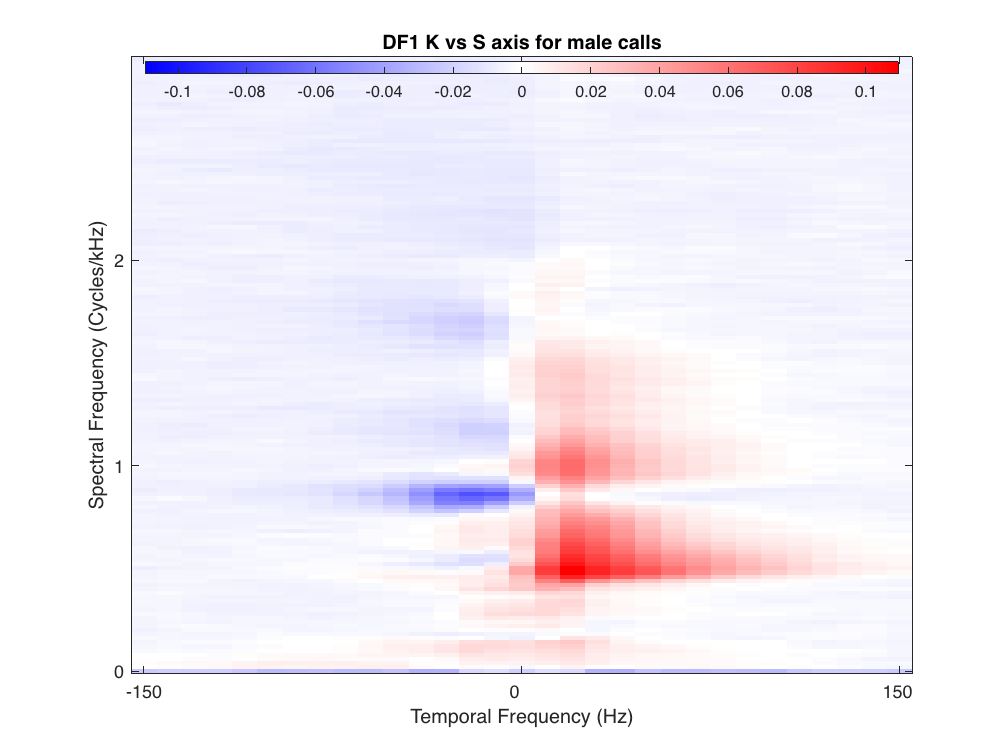

% plot the positive direction of the DF1 axis in the MPS space
    figure()
    plot_mps(PC_DF_males, MPS_mic_wf(IndWf),MPS_mic_wt, 60,nan,0,[0 max(MPS_mic_wf(IndWf).*10^3)], [-150 150]);
    title('DF1 K vs S axis for male calls')
Cmap = flip([ones(128,1) (0:1/127:1)' (0:1/127:1)';
flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)]);
colormap(Cmap)
Axis = caxis();
Lim = max(abs(Axis));
caxis([-Lim Lim])

Permutation DFA for females only

    SexDeafMic = SexDeaf(IndMicAudioGood);
    FemaleLogical = contains(SexDeafMic, 'F');
    SexDeafMic_F=SexDeafMic(FemaleLogical);
    
    % Find the optimal regularization parameters Delta and Gamma with a PC
    % input that explains 90% variance
    Mdl_DG_females = fitcdiscr(Score(FemaleLogical, 1:NPC),SexDeafMic(FemaleLogical), 'OptimizeHyperparameters', 'auto', 'HyperparameterOptimizationOptions', struct('Kfold',10), 'Prior', [0.5 0.5], 'SaveMemory', 'on', 'FillCoeffs', 'off');
    
    % Run the model with the best Delta and Gamma in cross validation and
    % get the Loss values accross validation sets
    Mdl = fitcdiscr(Score(FemaleLogical, 1:NPC),SexDeafMic(FemaleLogical), 'Delta', Mdl_DG_females.Delta, 'Gamma', Mdl_DG_females.Gamma, 'CrossVal','on', 'KFold', 10, 'Prior', [0.5 0.5], 'SaveMemory', 'on', 'FillCoeffs', 'off');
    L_females = kfoldLoss(Mdl, 'Mode', 'Individual');

    % Permutation of HD irrespective of ID
    Lrand_females = nan(NRandPerm,1);
    for bb=1:NRandPerm
        RandInd = randperm(length(SexDeafMic_F));
        Mdlrand = fitcdiscr(Score(FemaleLogical,1:NPC),SexDeafMic_F(RandInd), 'Delta', Mdl_DG_females.Delta, 'Gamma', Mdl_DG_females.Gamma,'CrossVal','on', 'KFold', 10, 'Prior', [0.5 0.5], 'SaveMemory', 'on', 'FillCoeffs', 'off');
        Lrand_females(bb) = kfoldLoss(Mdlrand);
    end

    % permutation of HD respecting ID
    C=nchoosek(1:6,3);
    Perm_females = [C(1:size(C,1)/2,:), flip(C((size(C,1)/2 +1) : end,:)), repmat(7:10,size(C,1)/2,1)];
    Lperm_females = nan(size(Perm_females,1),length(PC_val));
    BatIDMicGR = BatID(IndMicAudioGood);
    BatIDMicGR_F = BatIDMicGR(FemaleLogical);
    for bb=1:size(Perm_females,1)
        SexDeafMic_F_temp = SexDeafMic_F;
        BatSexDeaf_local = BatSexDeaf(Perm_females(bb,:));
        for bat=1:length(BatName)
            if sum(contains(BatIDMicGR_F,num2str(BatName(bat))))
                Ind = find(contains(BatIDMicGR_F,num2str(BatName(bat))));
                for ii=1:length(Ind)
                    SexDeafMic_F_temp{Ind(ii)} = BatSexDeaf_local{bat};
                end
            end
        end
        Mdlrand = fitcdiscr(Score(FemaleLogical,1:NPC),SexDeafMic_F_temp, 'Delta', Mdl_DG_females.Delta, 'Gamma', Mdl_DG_females.Gamma, 'CrossVal','on', 'KFold', 10, 'Prior', [0.5 0.5], 'SaveMemory', 'on', 'FillCoeffs', 'off');
        Lperm_females(bb) = kfoldLoss(Mdlrand);
    end

    % Rerun the DFA with all the data to obtain the filter
    Mdl = fitcdiscr(Score(FemaleLogical, 1:NPC),SexDeafMic(FemaleLogical), 'Delta', Mdl_DG_females.Delta, 'Gamma', Mdl_DG_females.Gamma, 'Prior', [0.5 0.5], 'SaveMemory', 'off', 'FillCoeffs', 'on');
    % Mdl.BetweenSigma is the p-by-p matrix, the between-class covariance, where p is the number of predictors.
    % Mdl.Sigma % Within-class covariance matrix or matrices. The dimensions depend on DiscrimType: 'linear'...
    %  (default) — Matrix of size p-by-p, where p is the number of predictors
    % The firt PC of the pca of the between class covariance matrix divided
    % by within class covariance matrix is the first filter of the DFA in
    % DFA input space (first PCA above)
    [PC_DFA,~] = pca(Mdl.Sigma \ Mdl.BetweenSigma);
    PC_DF_females = PC(:,1:NPC) * PC_DFA(:,1);
    PC_DF_females = reshape(PC_DF_females, sum(IndWf), length(MPS_mic_wt));
    
    fprintf(1, 'Classification performance between K and S female calls: %.1f%% +/-%.1f%%\nPermutation value (respecting ID): %.1f%% +/-%.1f%%\nPermutation value (irrespective of ID): %.1f%% +/-%.1f%%\nGamma:%.2f and Delta:%.1e\n', mean((1-L_females)*100), std((1-L_females)*100),mean((1-Lperm_females)*100), std((1-Lperm_females)*100),mean((1-Lrand_females)*100), std((1-Lrand_females)*100), Mdl_DG_females.Gamma, Mdl_DG_females.Delta)
    save(fullfile(LocalDataDir, 'Data4_DeafBats_PermDFA_AllCalls.mat'), 'Mdl_DG_females', 'L_females', 'Lrand_females', 'Lperm_females', 'Perm_females', 'PC_DF_females', 'MPS_mic_wf', 'IndWf', 'MPS_mic_wt', '-append')
    
    % plot the positive direction of the DF1 axis in the MPS space
    figure()
    plot_mps(PC_DF_females, MPS_mic_wf(IndWf),MPS_mic_wt, 60,nan,0,[0 max(MPS_mic_wf(IndWf).*10^3)], [-150 150]);
    title('DF1 K vs S axis for female calls')
    Cmap = flip([ones(128,1) (0:1/127:1)' (0:1/127:1)';
    flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)]);
    colormap(Cmap)
    Axis = caxis();
    Lim = max(abs(Axis));
    caxis([-Lim Lim])

Now for each acoustic group run a permutation DFA per sex

UGroup = unique(TmicAll7);
for gg=1:length(UGroup)
    GR = UGroup(gg);
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------Acoustic Group %d----------------------------\n', GR)
    [PC,Score,~, ~, VarExpl,~] = pca(MPS_mic_norm(TmicAll7==GR,:));
    save(fullfile(LocalDataDir, sprintf('Data4_DeafBats_PermDFA_AcGroup%d.mat', GR)), 'PC', 'Score', 'VarExpl')

(Plot the % variance explained by the PC) Not anymore we use the same PCA space as the one used for all calls

    figure()
    CSVarExpl = cumsum(VarExpl);
    plot(CSVarExpl, 'Linewidth',2)
    xlabel('# PC')
    ylabel(sprintf('%variance explained for Acoustic group %d', GR))
    NPC = find(cumsum(VarExpl)>80,1);
    text(100,95, sprintf('80%% variance explained with %d PC',NPC ))
    text(100,90, sprintf('%.1f%% variance explained with 40 PC', CSVarExpl(40)))

Run a DFA with both males and females

    DeafMicGR = Deaf(IndMicAudioGood(TmicAll7==GR));
    PC_val = [5:5:19 20:10:100];
    NRandPerm=10;
    NPC_i = floor(sum(TmicAll7==GR)^(1/2)/3); % Let's take at least 3 values to estimate each parameter in the variance covariance matrix
    NPC_opt_all = PC_val((abs(PC_val-NPC_i))==min(abs(PC_val-NPC_i)));
    NPC_opt_all = NPC_opt_all(1);
    
    % DFA
    L_All = nan(NRandPerm,length(PC_val));
    for pc=1:length(PC_val)
        Mdl = fitcdiscr(Score(TmicAll7==GR,1:PC_val(pc)),DeafMicGR, 'CrossVal','on', 'Prior', [0.5 0.5]);
        L_All(:,pc) = kfoldLoss(Mdl,'Mode', 'Individual');
    end
    
    Mdl.BetweenSigma % is the p-by-p matrix, the between-class covariance, where p is the number of predictors.
    Mdl.Sigma % Within-class covariance matrix or matrices. The dimensions depend on DiscrimType: 'linear'...
   %  (default) — Matrix of size p-by-p, where p is the number of predictors
   
    % Permutation of HD irrespective of ID
    Lrand_All = nan(NRandPerm,length(PC_val));
    for bb=1:NRandPerm
        RandInd = randperm(length(DeafMicGR));
        for pc=1:length(PC_val)
            Mdlrand = fitcdiscr(Score(TmicAll7==GR,1:PC_val(pc)),DeafMicGR(RandInd), 'CrossVal','on', 'Prior', [0.5 0.5]);
            Lrand_All(bb,pc) = kfoldLoss(Mdlrand);
        end
    end

    % permutation of HD respecting ID
    C=nchoosek(1:10,5);
    Perm_All = [C(1:size(C,1)/2,:), flip(C((size(C,1)/2 +1) : end,:))];
    Lperm_All = nan(size(Perm_All,1),length(PC_val));
    BatSexDeaf4DFA = BatSexDeaf([1:3, 7:8, 4:6, 9:10]); % reorder to place Deaf bats first in the list, then hearing bats
    BatName4DFA = BatName([1:3, 7:8, 4:6, 9:10]);
    BatIDMicGR = BatID(IndMicAudioGood(TmicAll7==GR));
    for bb=1:size(Perm_All,1)
        DeafMicGR_temp = DeafMicGR;
        BatSexDeaf_local = BatSexDeaf4DFA(Perm_All(bb,:));
        for bat=1:length(BatName4DFA)
            if sum(contains(BatIDMicGR,num2str(BatName4DFA(bat))))
                Ind = find(contains(BatIDMicGR,num2str(BatName4DFA(bat))));
                for ii=1:length(Ind)
                    DeafMicGR_temp{Ind(ii)} = strtok(BatSexDeaf_local{bat});
                end
            end
        end
        for pc=1:length(PC_val)
            Mdlrand = fitcdiscr(Score(TmicAll7==GR,1:PC_val(pc)), DeafMicGR_temp, 'CrossVal','on', 'Prior', [0.5 0.5]);
            Lperm_All(bb,pc) = kfoldLoss(Mdlrand);
        end

    end

    % Plot the figure
    figure()
    shadedErrorBar(PC_val, 100*(1-mean(L_All)),std(100*(1-L_All)),{'-','color',ColorCode(5,:)})
    xlabel('# PC')
    ylabel('% Classification correct')
    set(gca, 'YLim', [40 100])
    hold on
    H=hline(50, 'k--','Chance level');
    H.LineWidth = 2;
    hold on
    V = vline(NPC_opt_all, 'b--', 'Optimal #PC')
    V.LineWidth = 2;
    hold on
    shadedErrorBar(PC_val, 100*(1-mean(Lrand_All)),std(100*(1-Lrand_All)))
    hold on
    shadedErrorBar(PC_val, 100*(1-mean(Lperm_All)),std(100*(1-Lperm_All)))
    hold off
    title(sprintf('Acoustic Group %d DFA performance Hearing vs Deaf irrespective of sex', GR))
    text(10,55, 'Full permutation')
    text(10,77, 'Permutation respecting ID')


Permutation DFA for males only

    SexDeafMicGR = SexDeafMic(TmicAll7==GR);
    MaleLogical = contains(SexDeafMicGR, 'M');
    SexDeafMicGR_M=SexDeafMicGR(MaleLogical);
    Ind_GR_Males = logical((TmicAll7==GR).*contains(SexDeafMic, 'M'));
    NPC_i = floor(sum(Ind_GR_Males)^(1/2)/3); % Let's take at least 3 values to estimate each parameter in the variance covariance matrix
    NPC_opt_males = PC_val((abs(PC_val-NPC_i))==min(abs(PC_val-NPC_i)));
    NPC_opt_males = NPC_opt_males(1);

    %DFA
    L_males = nan(NRandPerm,length(PC_val));
    for pc=1:length(PC_val)
        Mdl = fitcdiscr(Score(Ind_GR_Males,1:PC_val(pc)),SexDeafMicGR(MaleLogical), 'CrossVal','on', 'Prior', [0.5 0.5]);
        L_males(:,pc) = kfoldLoss(Mdl, 'Mode', 'Individual');
    end

    % Permutation of HD irrespective of ID
    Lrand_males = nan(NRandPerm,length(PC_val));
    for bb=1:NRandPerm
        RandInd = randperm(length(SexDeafMicGR_M));
        for pc=1:length(PC_val)
            Mdlrand = fitcdiscr(Score(Ind_GR_Males,1:PC_val(pc)),SexDeafMicGR_M(RandInd), 'CrossVal','on', 'Prior', [0.5 0.5]);
            Lrand_males(bb,pc) = kfoldLoss(Mdlrand);
        end
    end

    % permutation of HD respecting ID
    Lperm_males = nan(3,length(PC_val));
    Perm_males = [1:6 7 9 8 10; 1:6 9 8 7 10; 1:6 7 9 10 8];
    BatIDMicGR = BatID(IndMicAudioGood(TmicAll7==GR));
    BatIDMicGR_M = BatIDMicGR(MaleLogical);
    for bb=1:3
        SexDeafMicGR_M_temp = SexDeafMicGR_M;
        BatSexDeaf_local = BatSexDeaf(Perm_males(bb,:));
        for bat=1:length(BatName)
            if sum(contains(BatIDMicGR_M,num2str(BatName(bat))))
                Ind = find(contains(BatIDMicGR_M,num2str(BatName(bat))));
                for ii=1:length(Ind)
                    SexDeafMicGR_M_temp{Ind(ii)} = BatSexDeaf_local{bat};
                end
            end
        end
        for pc=1:length(PC_val)
            Mdlrand = fitcdiscr(Score(Ind_GR_Males,1:PC_val(pc)),SexDeafMicGR_M_temp, 'CrossVal','on', 'Prior', [0.5 0.5]);
            Lperm_males(bb,pc) = kfoldLoss(Mdlrand);
        end
    end
    
    % plot figure
    figure()
    shadedErrorBar(PC_val, 100*(1-mean(L_males)),std(100*(1-L_males)),{'-','color',ColorCode(1,:)})
    xlabel('# PC')
    ylabel('% Classification correct')
    set(gca, 'YLim', [40 100])
    hold on
    H=hline(50, 'k--','Chance level');
    H.LineWidth = 2;
    hold on
    V = vline(NPC_opt_males, 'b--', 'Optimal #PC')
    V.LineWidth = 2;
    hold on
    shadedErrorBar(PC_val, 100*(1-mean(Lrand_males)),std(100*(1-Lrand_males)))
    hold on
    shadedErrorBar(PC_val, 100*(1-mean(Lperm_males)),std(100*(1-Lperm_males)))
    hold off
    title(sprintf('Acoustic Group %d DFA performance Male Hearing vs Deaf',GR))
    text(60,55, 'Full permutation')
    text(60,82, 'Permutation respecting ID')


Permutation DFA for females only

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Group 1----------------------------


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [20 20]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


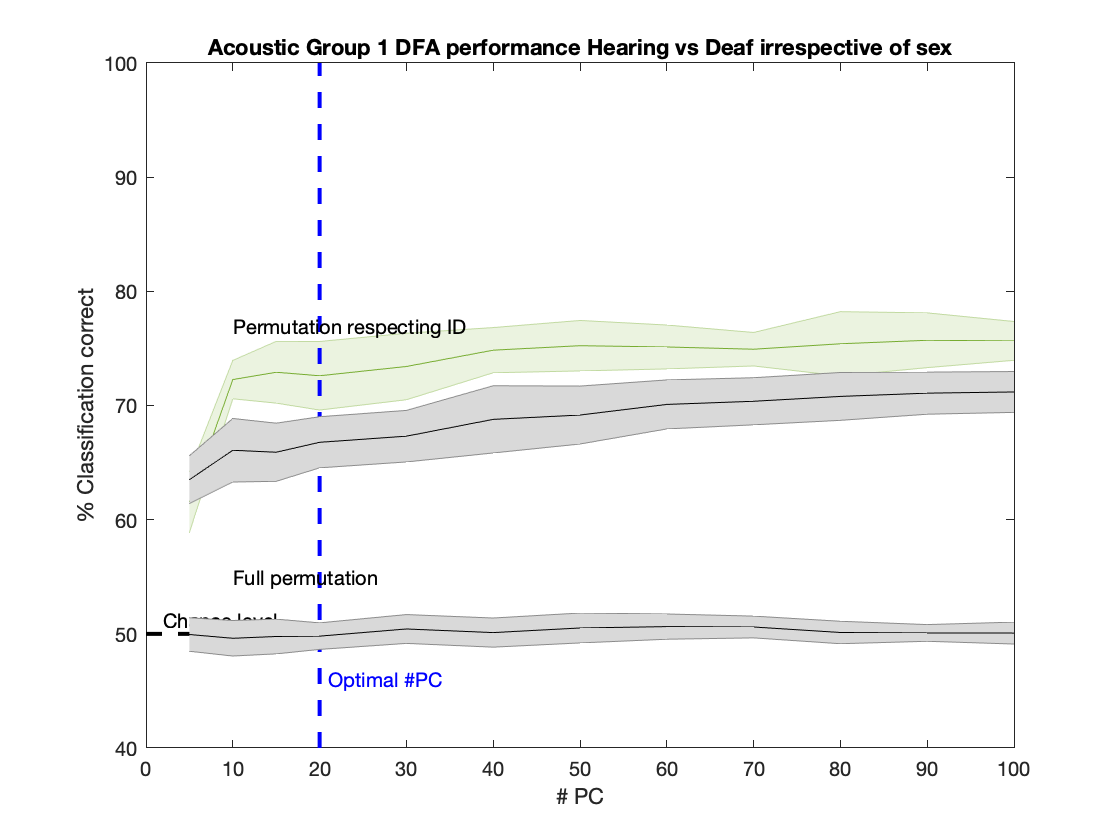

V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [10 10]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


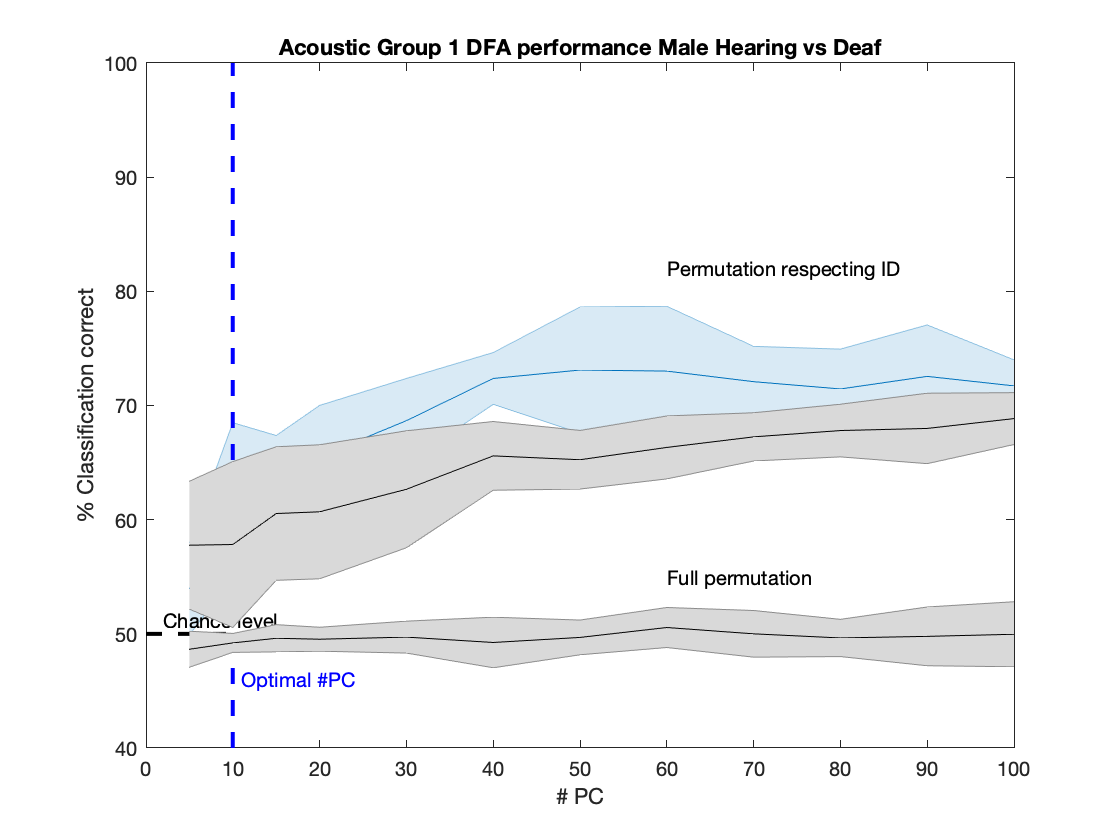

V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [15 15]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


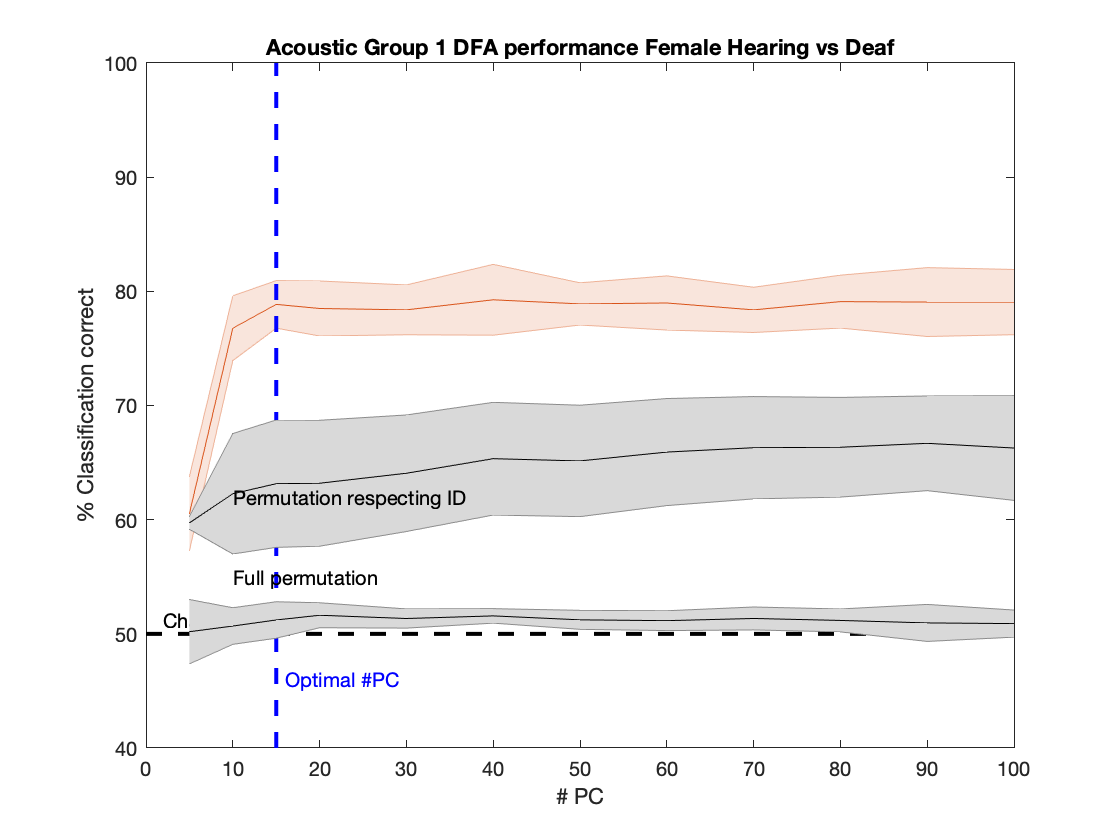

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Group 2----------------------------


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [15 15]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


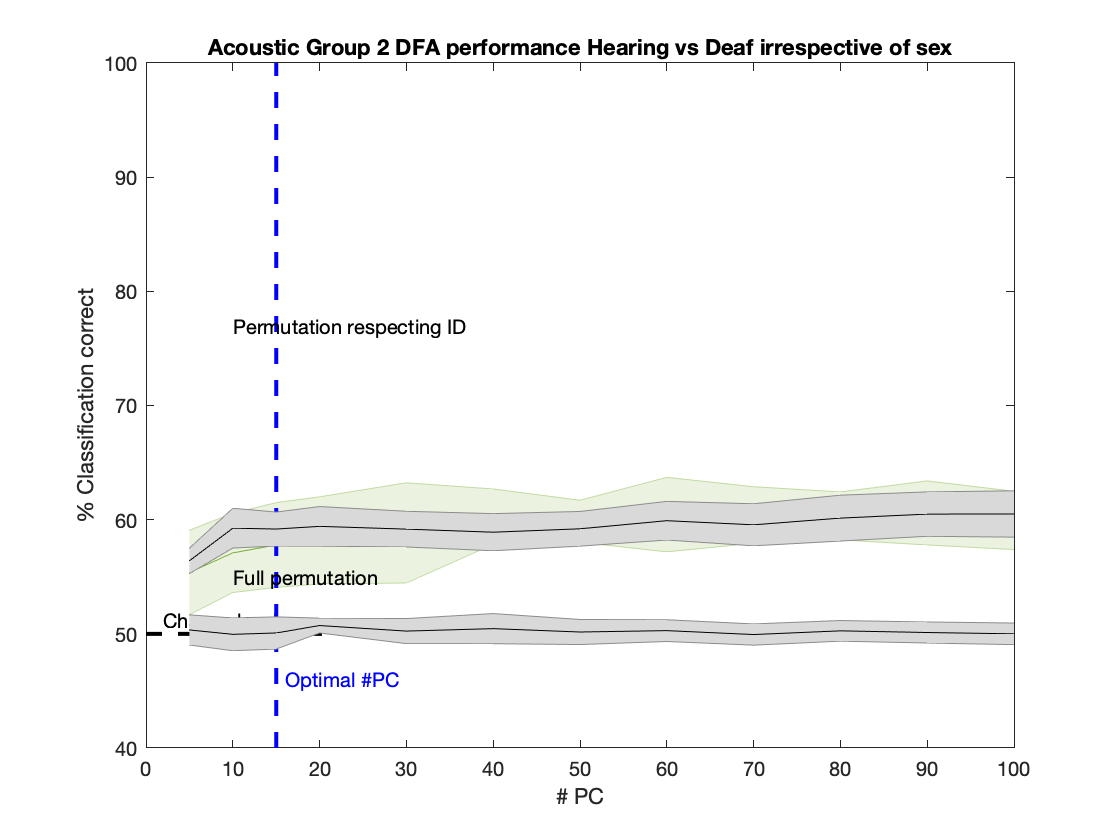

V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [15 15]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


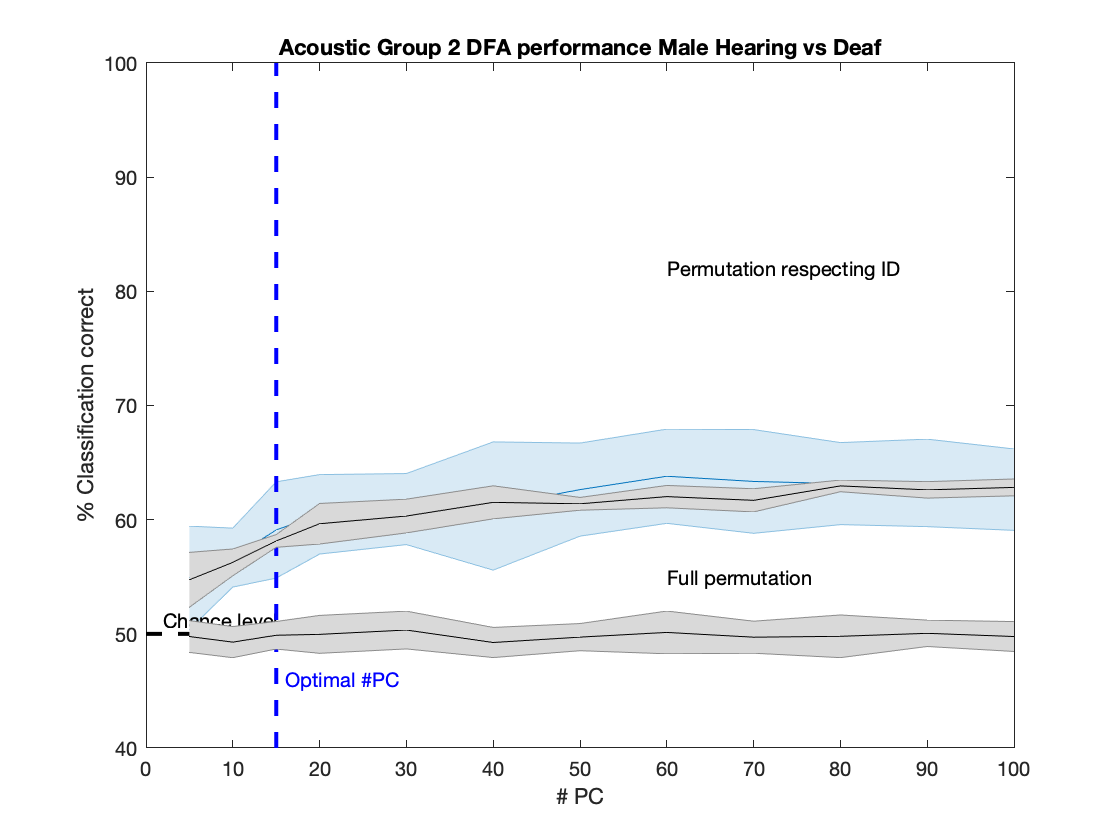

V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [10 10]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Group 3----------------------------


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [20 20]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


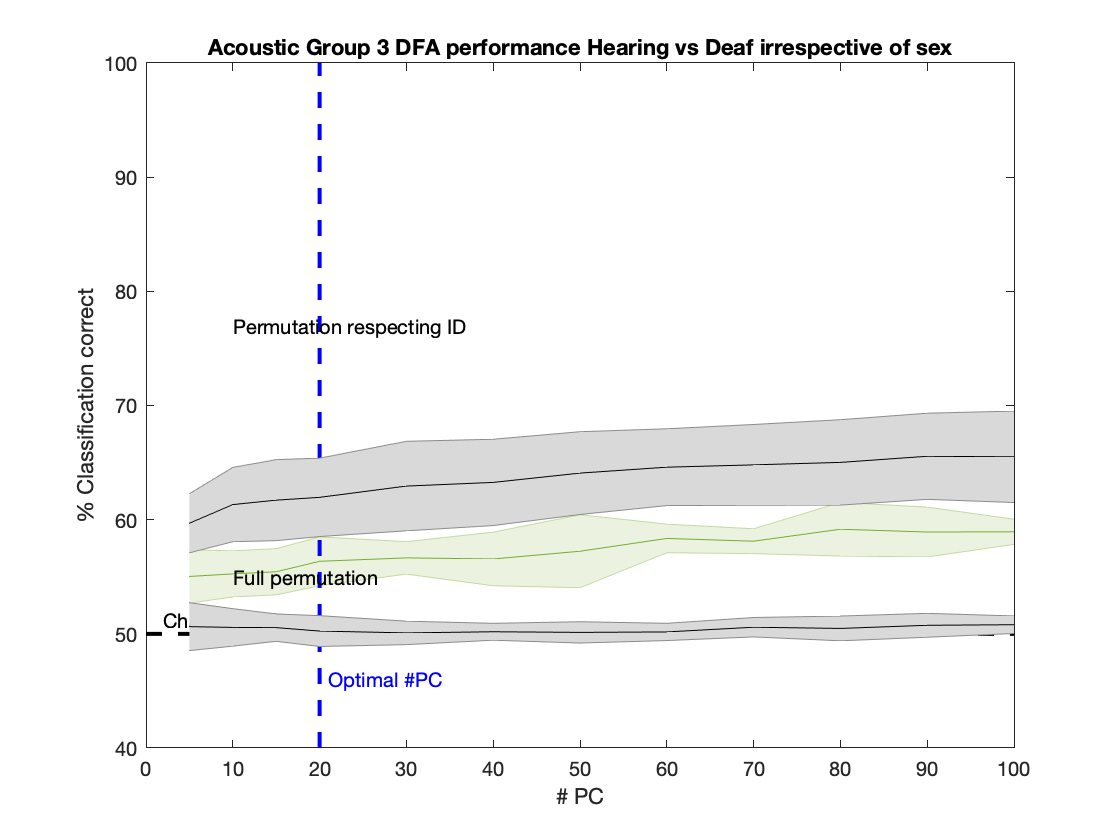

V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [15 15]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


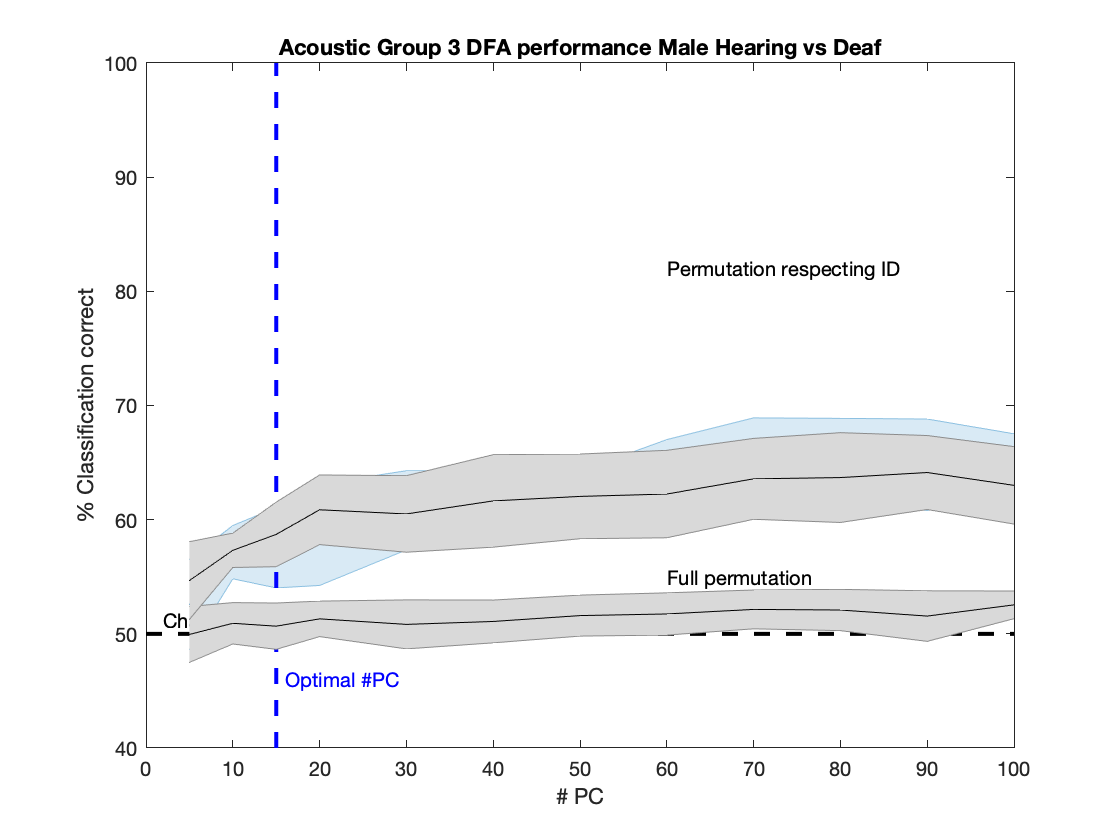

V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [20 20]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Group 4----------------------------


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [20 20]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [15 15]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [15 15]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Group 5----------------------------


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [20 20]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [20 20]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [5 5]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Group 6----------------------------


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [20 20]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [20 20]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [15 15]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Group 7----------------------------


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [20 20]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [10 10]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


V =   Line (vline) with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [15 15]
              YData: [40 100]
              ZData: [1×0 double]

  Show all properties


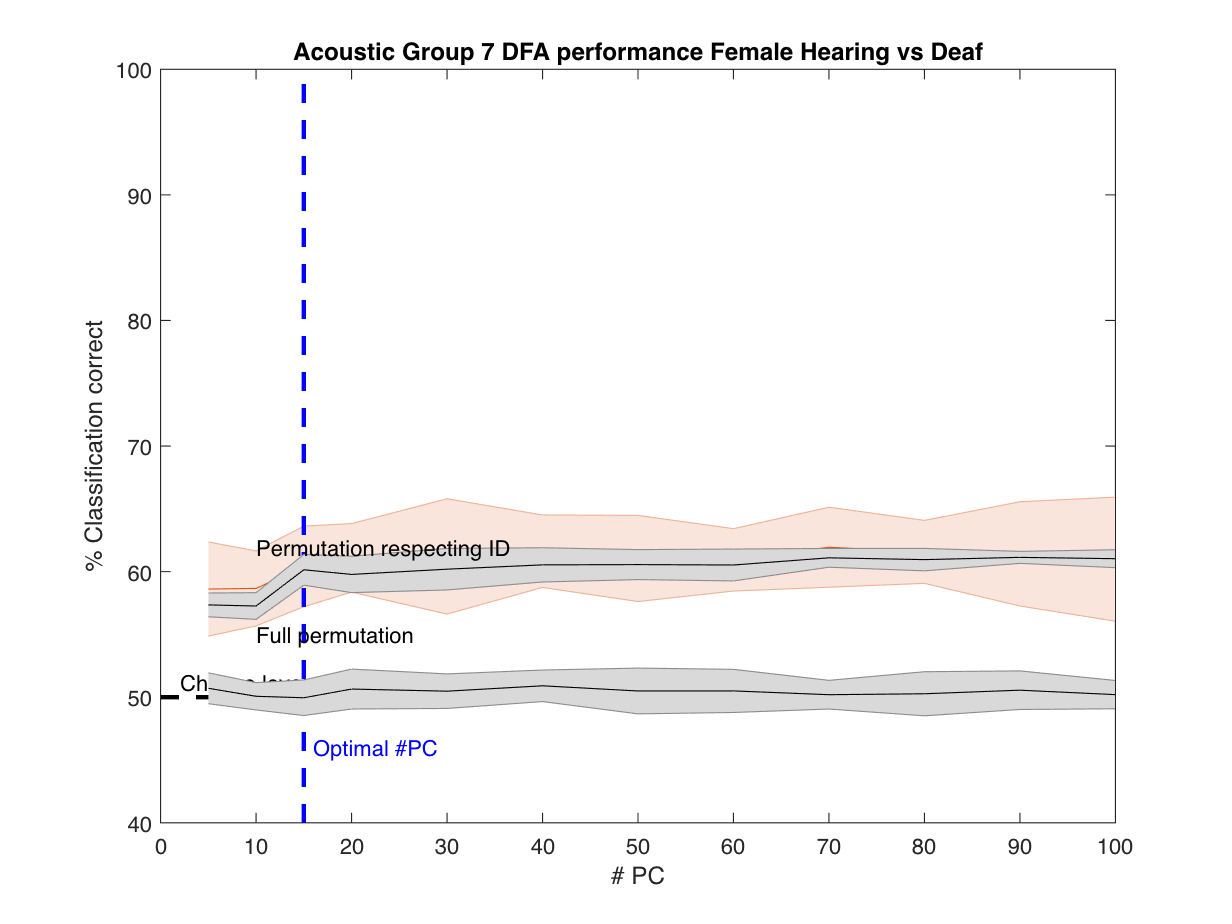

    SexDeafMicGR = SexDeaf(IndMicAudioGood(TmicAll7==GR));
    FemaleLogical = contains(SexDeafMicGR, 'F');
    SexDeafMicGR_F=SexDeafMicGR(FemaleLogical);
    Ind_GR_Females = logical((TmicAll7==GR).*contains(SexDeafMic, 'F'));
    NPC_i = floor(sum(Ind_GR_Females)^(1/2)/3); % Let's take at least 3 values to estimate each parameter in the variance covariance matrix
    NPC_opt_females = PC_val((abs(PC_val-NPC_i))==min(abs(PC_val-NPC_i)));
    NPC_opt_females = NPC_opt_females(1);

    L_females = nan(NRandPerm,length(PC_val));
    for pc=1:length(PC_val)
        Mdl = fitcdiscr(Score(Ind_GR_Females,1:PC_val(pc)),SexDeafMicGR(FemaleLogical), 'CrossVal','on', 'Prior', [0.5 0.5]);
        L_females(:,pc) = kfoldLoss(Mdl, 'Mode', 'Individual');
    end
    
    % Permutation of HD irrespective of ID
    Lrand_females = nan(NRandPerm,length(PC_val));
    for bb=1:NRandPerm
        RandInd = randperm(length(SexDeafMicGR_F));
        for pc=1:length(PC_val)
            Mdlrand = fitcdiscr(Score(Ind_GR_Females,1:PC_val(pc)),SexDeafMicGR_F(RandInd), 'CrossVal','on', 'Prior', [0.5 0.5]);
            Lrand_females(bb,pc) = kfoldLoss(Mdlrand);
        end
    end

    % permutation of HD respecting ID
    C=nchoosek(1:6,3);
    Perm_females = [C(1:size(C,1)/2,:), flip(C((size(C,1)/2 +1) : end,:)), repmat(7:10,size(C,1)/2,1)];
    Lperm_females = nan(size(Perm_females,1),length(PC_val));
    BatIDMicGR = BatID(IndMicAudioGood(TmicAll7==GR));
    BatIDMicGR_F = BatIDMicGR(FemaleLogical);
    for bb=1:size(Perm_females,1)
        SexDeafMicGR_F_temp = SexDeafMicGR_F;
        BatSexDeaf_local = BatSexDeaf(Perm_females(bb,:));
        for bat=1:length(BatName)
            if sum(contains(BatIDMicGR_F,num2str(BatName(bat))))
                Ind = find(contains(BatIDMicGR_F,num2str(BatName(bat))));
                for ii=1:length(Ind)
                    SexDeafMicGR_F_temp{Ind(ii)} = BatSexDeaf_local{bat};
                end
            end
        end
        for pc=1:length(PC_val)
            Mdlrand = fitcdiscr(Score(Ind_GR_Females,1:PC_val(pc)),SexDeafMicGR_F_temp, 'CrossVal','on', 'Prior', [0.5 0.5]);
            Lperm_females(bb,pc) = kfoldLoss(Mdlrand);
        end

    end

    % Plot figure
    figure()
    shadedErrorBar(PC_val, 100*(1-mean(L_females)),std(100*(1-L_females)),{'-','color',ColorCode(2,:)})
    xlabel('# PC')
    ylabel('% Classification correct')
    set(gca, 'YLim', [40 100])
    hold on
    H=hline(50, 'k--','Chance level');
    H.LineWidth = 2;
    hold on
    V = vline(NPC_opt_females, 'b--', 'Optimal #PC')
    V.LineWidth = 2;
    hold on
    shadedErrorBar(PC_val, 100*(1-mean(Lrand_females)),std(100*(1-Lrand_females)))
    hold on
    shadedErrorBar(PC_val, 100*(1-mean(Lperm_females)),std(100*(1-Lperm_females)))
    hold off
    title(sprintf('Acoustic Group %d DFA performance Female Hearing vs Deaf', GR))
    text(10,55, 'Full permutation')
    text(10,62, 'Permutation respecting ID')

    save(fullfile(LocalDataDir, sprintf('Data4_DeafBats_PermDFA_AcGroup%d.mat', GR)), 'GR','L_All', 'L_males', 'L_females', 'Lrand_All', 'Lrand_males', 'Lrand_females', 'Lperm_All', 'Lperm_males', 'Lperm_females', 'Perm_All', 'Perm_males', 'Perm_females', 'NPC_opt_all','NPC_opt_males','NPC_opt_females')
end

Calculate the genelarized variance for males and females calls in the PCA space (determinant of the variance co-variance matrix). We only take the first 100 PC for this calculation, similar to what is done for the DFA.

Caluclations per bat

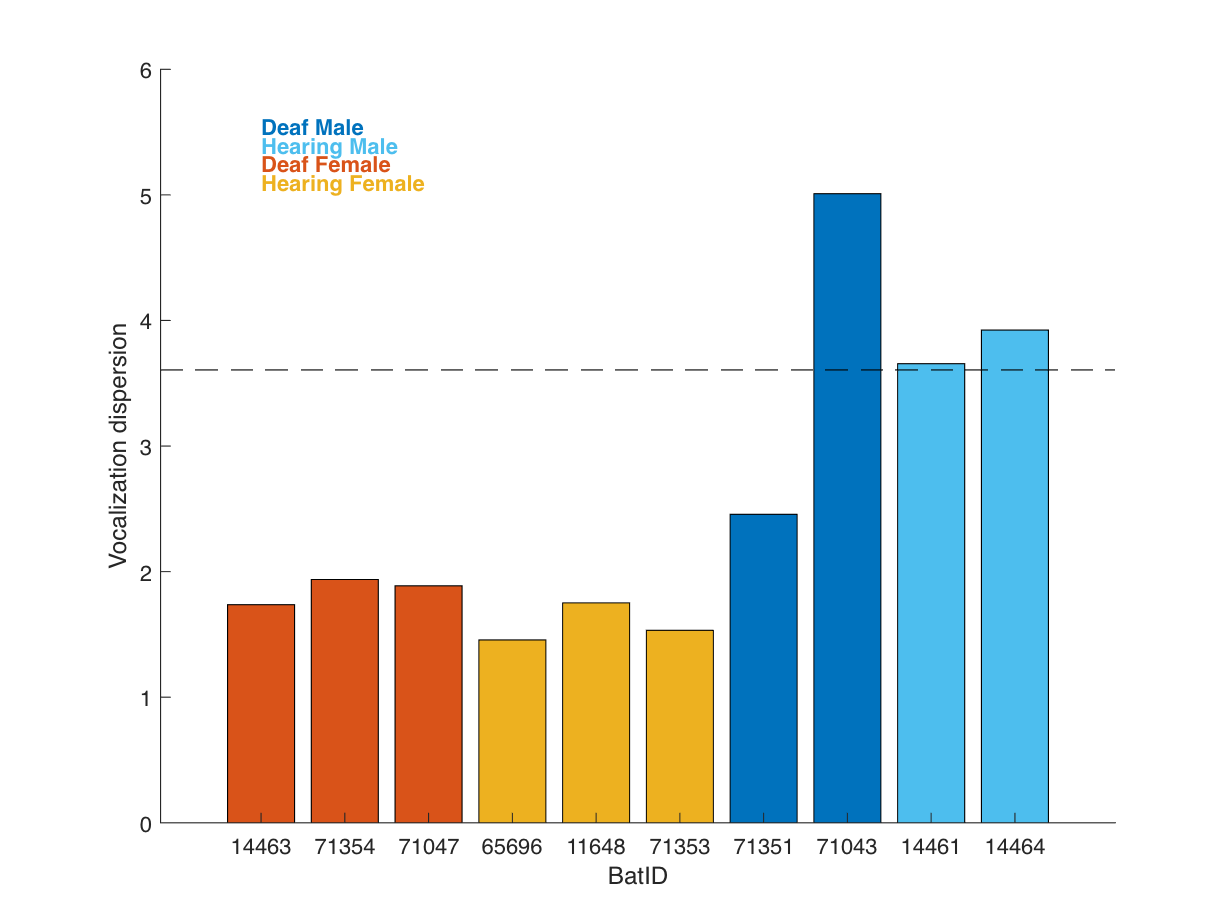

NPC =100;
BatIDMic = str2double(BatID(MicAudioGood01));
DValues = nan(length(BatName),1);
for bb=1:length(BatName)
    VCoVMat = cov(Score(BatIDMic==BatName(bb),1:NPC));
    DValues(bb) = (det(VCoVMat))^(1/(2*NPC));
end
DMax = (det(cov(Score(:,1:NPC))))^(1/(2*NPC));

CData = nan(length(BatName),3);
for bb=1:length(BatName)
    CData(bb,:) = UCSexDeaf(strcmp(USexDeaf,BatSexDeaf{bb}),:);
end

figure()
B=bar(1:10, DValues,'FaceColor', 'flat');
B.CData = CData;
xlabel('BatID')
B.Parent.XTickLabel = BatName;
ylabel('Vocalization dispersion')
for ct=1:length(USexDeaf)
    text(1,B.Parent.YLim(2)-diff(B.Parent.YLim)*(2+ct)/40, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
end
hold on
box off
hline(DMax, '--k')
hold off

fprintf(1,'Hearing female Vocalization dispersion: %.1f +- %.1f\n', mean(DValues(contains(BatSexDeaf, 'Hearing Female'))), std(DValues(contains(BatSexDeaf, 'Hearing Female'))));

Hearing female Vocalization dispersion: 1.6 +- 0.2


fprintf(1,'Hearing female Vocalization dispersion: %.1f +- %.1f\n', mean(DValues(contains(BatSexDeaf, 'Hearing Male'))), std(DValues(contains(BatSexDeaf, 'Hearing Male'))));

Hearing female Vocalization dispersion: 3.8 +- 0.2


function [CB,Im,MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
    if nargin<4
        DBNOISE=60;
    end

    if nargin<6
        Log=1;
    end

    if nargin<7
        YLim = [0 max(Wf*10^3)];
    end
    if nargin<8
        XLim = [min(Wt) max(Wt)];
    end
    if nargin<5
        CLim = nan;
    end
    if nargin<9
        TwoDfilter=0;
    end
    
    Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
    Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
    MPS = MPS(Wf_i, Wt_i);
    Wf_local = Wf(Wf_i);
    Wt_local = Wt(Wt_i);
    if Log
        MPS4plot = 10*log10(MPS);
        MaxMPS = max(max(MPS4plot));
        MinMPS = MaxMPS-DBNOISE;
        MPS4plot(MPS4plot < MinMPS) = MinMPS;
    else
        MPS4plot = MPS; 
    end

    if TwoDfilter
        MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
    end
    
    %             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
    Im = imagesc(MPS4plot);
    axis xy
    colormap(Im.Parent,'jet');
    CB=colorbar();
%     CB.YTick=0;
%     CB.YTickLabel=0;
    CB.Units = 'inches';
    CB.Location='north';
    CB.Position(4) = 0.1;
    CB.Position(2) = CB.Position(2) + 0.2;
    xlabel('Temporal Frequency (Hz)')
    ylabel('Spectral Frequency (Cycles/kHz)')
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_local*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(ceil(Wt_local*10^-1))*10^1;
    XTickLabel = [-MaxWt 0 MaxWt];
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    if ~isnan(CLim)
        PlotMPS = gca;
        PlotMPS.CLim = CLim;
    end
end